# Local Linearization of a Nonlinear Dynamical Model

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction 

In the previous lesson, we have seen that implementation of MHOPC-2 using nonlinear dynamic model results in large computation time, which makes it difficult to implement in the real time. A possible remedy is to develop control relevant linear perturbation models, which are locally valid and these can be used for design and implementation of MHOPC-2. The classical control literature uses this approach for controller design. The advantage of linear ODEs/difference equations is that they can be solved analytically and it is easy to analyze the local stability or design a controller based on them that ensures the desired performance.  We assume that a well developed mechanistic model for the system under consideration is available with us for controller synthesis.

The overall game plan is explained in Figure 1.  The nonlinear plant dynamics are represented with a set of ODEs. Using Taylor series expansion, we convert them to a linear set of differential equations and subsequently into linear difference equations. These are then used for controller design such that the nominal closed loop system is locally stable and the desired performance specifications are (locally) achieved. 

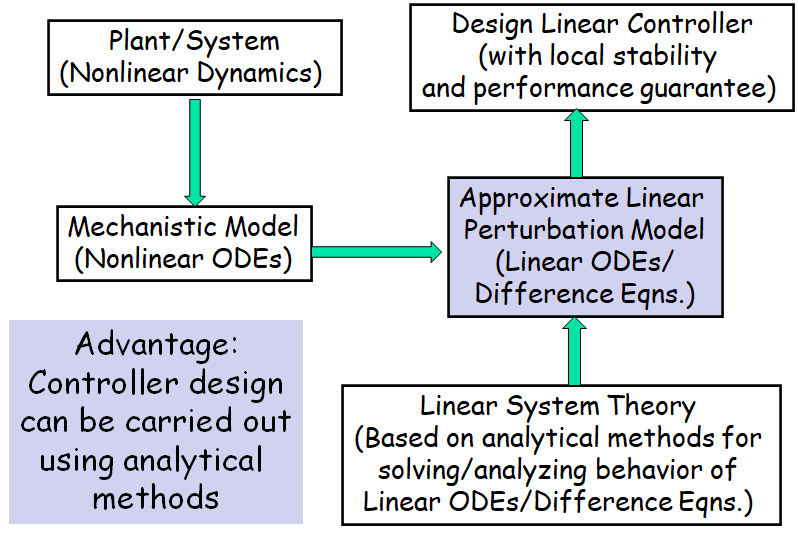

**Figure 1: Controller Synthesis using Local Linearization - Overall Game Plan **

 In this lesson, we will see how to obtain a local linear model from a given nonlinear model both analytically and also using MATLAB. 

**Learning Objectives: **

- Given a mechanistic nonlinear dynamic model as a set of ODEs, develop a control relevant local linear perturbation model (i.e. a set of linear ODEs)  

## Local Linearization of a Nonlinear Dynamic Model

Let us start with a general nonlinear ODE model of a plant. 

### **Nonlinear Dynamic Model**

Consider a Lumped Parameter Model, where the state dynamics are given by 

   $\frac{\mathrm{dX}}{\mathrm{dt}}=f\left(X\left(t\right),U\left(t\right),D\left(t\right)\right)$ ---------(1)

with a measurement model

 $Y\left(t\right)=g\left(X\left(t\right)\right)\;$---------(2)

where **f and g** are nonlinear maps and 

- $X\in R^n$ represents state variables

- $U\in R^{m} $ represents manipulated inputs 

- $D\in R^d$ represent disturbance inputs 

- $Y\in R^{r}$ represents measured outputs.

The state dynamics are given by a nonlinear map $f\left(\ldotp \right)$ that relates the rate of change of states with the current state, input and disturbances. For example, the  mechanistic model for Quadruple Tank system described earlier([Mechanistic Model for Q Tank Process](matlab:open('../2.Quadruple_Tank_Dynamical_Model/L02_DynamicsofMVPRocess.mlx'))) can be expressed in form (1) as follows:  

$\frac{d}{\mathrm{dt}}\left\lbrack \begin{array}{c}
h_1 \\
h_2 \\
h_3 \\
h_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\frac{a_1 }{A_1 }\sqrt{2gh_1 }+\frac{a_1 }{A_1 }\sqrt{2gh_1 }+\frac{\gamma_1 k_1 }{A_1 }v_1 \\
-\frac{a_2 }{A_2 }\sqrt{2gh_2 }+\frac{a_2 }{A_2 }\sqrt{2gh_2 }+\frac{\gamma_2 k_2 }{A_2 }v_2 \\
-\frac{a_3 }{A_3 }\sqrt{2gh_3 }+\frac{\left(1-\gamma_2 \right)k_2 }{A_3 }v_2 +\frac{\gamma_3 k_1 }{A_3 }F\\
-\frac{a_4 }{A_4 }\sqrt{2gh_4 }+\frac{\left(1-\gamma_1 \right)k_1 }{A_4 }v_1 +\frac{\left({1-\gamma }_3 \right)k_1 }{A_3 }F
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f_1 \left(X,\;U,D\right)\\
f_2 \left(X,\;U,D\right)\\
f_3 \left(X,\;U,D\right)\\
f_4 \left(X,\;U,D\right)
\end{array}\right\rbrack$-----------(3a)

where

 $X\equiv \left\lbrack \begin{array}{c}
h_1 \\
h_2 \\
h_3 \\
h_4 
\end{array}\right\rbrack ,\;\;\;\;U\equiv \left\lbrack \begin{array}{c}
v_1 \\
v_2 
\end{array}\right\rbrack \;\mathrm{and}\;D\equiv F$  ------(3b)

Local linearization of nonlinear model (1) and (2)  will give us a linear dynamic model, which is amenable  to analytical treatment but only locally accurate. The local linearization of the dynamic  model (1) and (2) is carried out using the Taylor series approximation of operators f(.) and g(.) at an ***equilibrium or steady state ***operating point of model (1). 

### ** Equilibrium Operating Point **

To obtain linear perturbation model from the nonlinear model, we need to first define the operating point at which the model is to be linearized.  An **operating point** (also known as a **steady-state point**, **equilibrium point**, or **bias point**) is a specific set of values for a system’s **inputs**, **outputs**, and **states** at which the system is in **steady-state operation, **meaning it is not changing over time. Let us assume that inputs to the system are held constant at some chosen (desired) values 

$U\left(t\right)=U_s \;\;\;\mathrm{and}\;\;\;D\left(t\right)=D_s \;\;\mathrm{for}\;\mathrm{all}\;t\ge 0\;$.  ------(4)

Then, the equilibrium point is governed by the following set of equations 

  $\begin{array}{l}
\frac{\mathrm{dX}}{\mathrm{dt}}=f\left(X_s ,U_s ,D_s \right)=\bar{0} \;\;\\
\;\;Y_s =g\left(X_s \right)
\end{array}$   ------(5)

In other words, when the system is at the equilibrium point, then

 $X\left(t\right)=X_s \;\;\;\mathrm{and}\;\;\;Y\left(t\right)=Y_s \;\;\;\mathrm{for}\;\mathrm{all}\;t\ge 0\;$  ------(6)

Set of equations (4) are typically nonlinear algebraic equations and need to be solved using a numerical scheme such as Newton-Raphson method or nonlinear optimization based solver, such as `fsolve `function in MATLAB Optimization Toolbox. Let us carry out this exercise for the Quadruple Tank system. The ODE model parameters for this system are listed in Table 1 and Table 2 

**Table 1: Quadruple Tank Model Parameters **

**Table 2: Quadruple Tank - Operating Input Conditions**

%%%%Click to Run the Code
 
close all    % close all open figures 
clear all     % clear work space 


 **Note: **For ease of communication between different MATLAB functions, all parameters are saved in a structure named QTank. 

global QTank  % Define global variables 

% Four Tank system: Initialize model parameters
QTank.a1 = 0.071 ;    % cm^2 (Area of outlet tube for Tank 1)
QTank.A1 = 28    ;    % cm^2 (Area of tank 1)
QTank.a3 = 0.071 ;    % cm^2 (Area of outlet tube for Tank 3)
QTank.A3 = 28    ;    % cm^2 (Area of tank 3)
QTank.a2 = 0.057 ;    % cm^2 (Area of outlet tube for Tank 2)
QTank.A2 = 32    ;    % cm^2 (Area of tank 2)
QTank.a4 = 0.057 ;    % cm^2 (Area of outlet tube for Tank 4)
QTank.A4 = 32    ;    % cm^2 (Area of tank 4)

**Task 1:** Q Tank has two Steady State Operating conditions. Specify Operating Condition. Select **Minimum Phase or Non-minimum Phase **

operating_pt=1  

operating_pt = 1

% Model parameters at minimum phase (P-) and non-minimum phase (P+) operating points
if ( operating_pt == 1 )                                  % Minimum phase system
    QTank.gam1 = 0.7 ;    % cm^3/Vs
    QTank.k1 =   3.33 ;    
    QTank.gam2 = 0.6 ;    % cm^3/Vs
    QTank.k2 =   3.35 ;
    QTank.Us = [ 3 3 ]' ;           % Steady state input 
elseif ( operating_pt == 2 )                           % Non-Minimum phase system 
    QTank.gam1 = 0.43 ;    % cm^3/Vs
    QTank.k1 =   3.14 ;
    QTank.gam2 = 0.34 ;    % cm^3/Vs
    QTank.k2 =   3.29 ;
    QTank.Us = [ 3.15 3.15 ]' ;   % Steady state input 
end 

**Task 2:** The Disturbance Flow Input can be set to a value between $0-2\;{\mathrm{cm}}^3 /\sec$, using the slider below. For example, we can set it equal to $1\;{\mathrm{cm}}^3 /\sec$. 

QTank.Ds=1;
QTank.gam3 = 0.4 ;   % For disturbance input 


To get the steady state values of levels in the four tanks we use **fsolve function in MATLAB. **[**(https://in.mathworks.com/help/optim/ug/fsolve.html**](http://(https//in.mathworks.com/help/optim/ug/fsolve.html)**)**

**QTank_SteadyState** is a function used by fsolve for equilibrium point computation of the Modified Quadruple Tank System 

% Find Equilibrium/ Steady State Operating Point for the specified inputs 
if ( operating_pt == 1 )                           % Minimum phase system              
   Xs0 = [ 12.4 12.7 1.8 1.4 ]' ;    % Initial Guess 
elseif ( operating_pt == 2 )                    % Non-Minimum phase system  
   Xs0 = [ 12.6 13 4.8 4.9 ]' ;       % Initial Guess
end  
oldopts = optimset ;
tolerance = 1e-10 ;
options = optimset(oldopts,'MaxIter', 1e6, 'Display','off', 'TolFun',tolerance, 'TolX', tolerance) ;
QTank.Xs = fsolve(@QTank_SteadyState, Xs0, options ) ;
 
% This function is used by fsolve for equilibrium point computation
% of the Modified Quadruple Tank System 

function Xdot = QTank_SteadyState( Xs )

global QTank

gc = 981 ;  % (cm/s^2) gravitational constant

h(1) = Xs(1) ; h(2) = Xs(2) ; h(3) = Xs(3) ; h(4) = Xs(4) ;

hdot(1) = -(QTank.a1 / QTank.A1) * (2 * gc * h(1))^0.5 ;
hdot(1) = hdot(1) + (QTank.a3 / QTank.A1) * (2 * gc * h(3))^0.5 ;
hdot(1) = hdot(1) + (QTank.gam1 * QTank.k1 / QTank.A1) * QTank.Us(1) ;

hdot(2) = -(QTank.a2 / QTank.A2) * (2 * gc * h(2))^0.5 ;
hdot(2) = hdot(2) + (QTank.a4 / QTank.A2) * (2 * gc * h(4))^0.5 ;
hdot(2) = hdot(2) + (QTank.gam2 * QTank.k2 / QTank.A2) * QTank.Us(2) ;

hdot(3) = -(QTank.a3 / QTank.A3) * (2 * gc * h(3))^0.5 ;
hdot(3) = hdot(3) + ((1-QTank.gam2)*QTank.k2 / QTank.A3) * QTank.Us(2) ;
hdot(3) = hdot(3) + (QTank.gam3/ QTank.A3) * QTank.Ds  ;
hdot(4) = -(QTank.a4 / QTank.A4) * (2 * gc * h(4))^0.5 ;
hdot(4) = hdot(4) + ((1-QTank.gam1) * QTank.k1 / QTank.A4) * QTank.Us(1) ;
hdot(4) = hdot(4) + ((1-QTank.gam3)/ QTank.A4) * QTank.Ds  ;

Xdot = hdot' ;
end

 The Steady State Inputs are 

display(QTank.Us')

     3     3



` Steady State Levels corresponding to the specified steady state input is as follows: `

display(QTank.Xs')

   13.1699   14.5390    1.9753    2.0297



Note that this system has infinite number of equilibrium points and for each choice of independent inputs$\left(U_s ,D_s \right)$, we get a different operating point $\left(X_s ,Y_s \right)$.  For example, the  level 1 and 2 as a function of the two input flows are as shown below in Figure 2a and Figure 2b, corresponding to `minimum phase operating point`

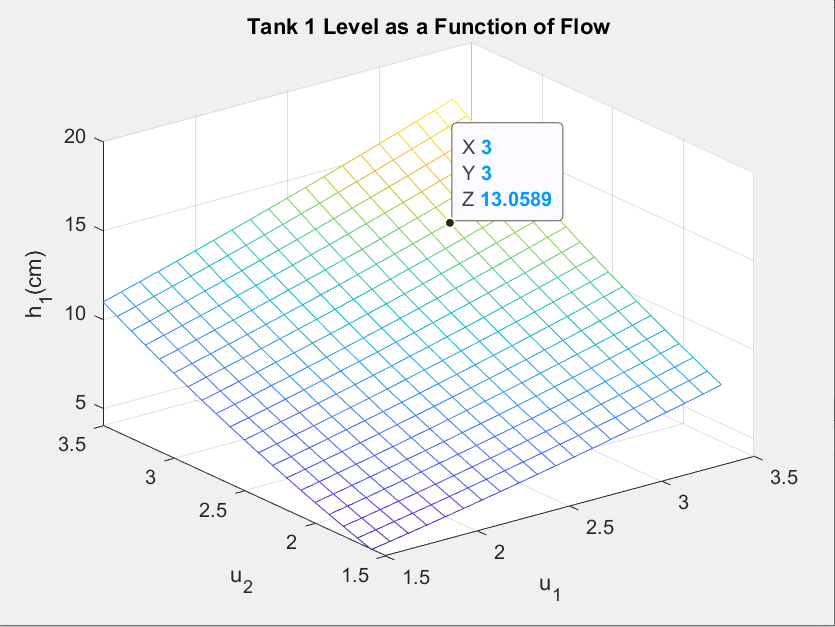

**Figure 2 a: Steady State Operating Point Level 1**

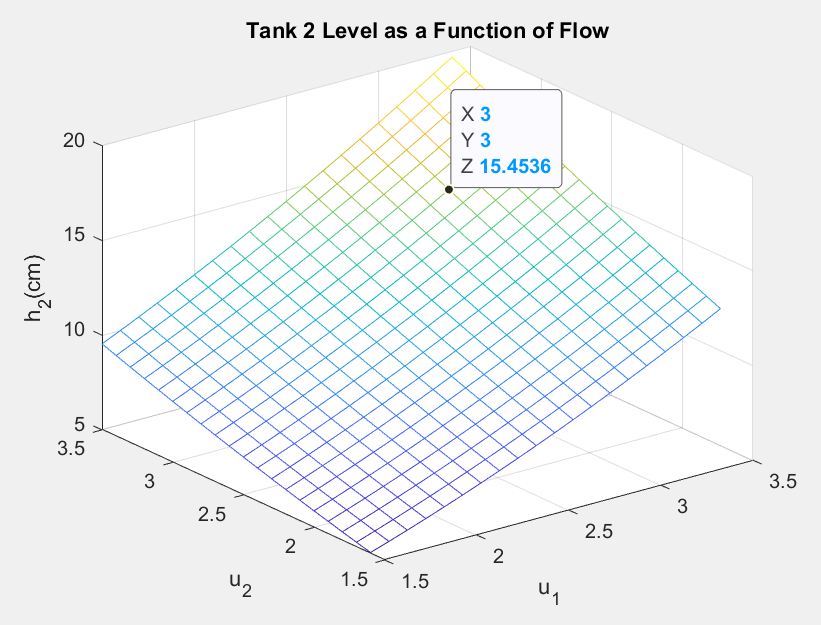

**Figure 2 b: Steady State Operating Point Level 2**

The specific equilibrium values obtained for disturbance flows equal to $1\;{\mathrm{cm}}^3 /\sec$ are listed in Table 3. We will be using these as the nominal operating conditions in the rest of the course.

**Table 3: Equilibrium or Steady State Operating Points **

## **Development of Linear Perturbation State Space Model**

Such a model is obtained by applying Taylor Series Expansion to the nonlinear function $f$ given in equation (1)  and retaining only the terms upto first order perturbations from the point of linearization.  Let $\left(X_s ,U_s ,D_s \right)$ represent the equilibrium point at which the linearization is to be carried out.  For the nonlinear ODE model (1), applying the multivariable Taylor series expansion $f\left(X\left(t\right),U\left(t\right),D\left(t\right)\right)$  in the neighborhood of $\left(X_s ,U_s ,D_s \right)$ and neglecting the terms higher than the first order, we arrive at the following approximate dynamic model 

$\begin{array}{l}
\frac{\mathrm{dX}}{\mathrm{dt}}\cong f\left(X_s ,U_s ,D_s \right)+{\left\lbrack \frac{\partial f}{\partial X}\right\rbrack }_{\left(\bullet \right)} x\left(t\right)+{\left\lbrack \frac{\partial f}{\partial U}\right\rbrack }_{\left(\bullet \right)} u\left(t\right)+{\left\lbrack \frac{\partial f}{\partial D}\right\rbrack }_{\left(\bullet \right)} d\left(t\right)\\
x\left(t\right)\equiv X\left(t\right)-X_s \;,\;\;\;u\left(t\right)\equiv U\left(t\right)-U_s \;\;\;\mathrm{and}\;\;\;d\left(t\right)=D\left(t\right)-D_s 
\end{array}$  --------(7)

where $\bullet =\left(X_s ,U_s ,D_s \right)$. Similarly, for the measurement model, we can apply multivariable Taylor series expansion to arrive at the following approximate model 

$Y\left(t\right)\cong g\left(X_s \right)+{\left\lbrack \frac{\partial g}{\partial X}\right\rbrack }_{\left(X_s \right)} \left\lbrack X\left(t\right)-X_s \right\rbrack =Y_s +C\;x\left(t\right)$ ------------(8)

where   $C\equiv {\left\lbrack \frac{\partial g}{\partial X}\right\rbrack }_{\left(X_s \right)}$. The Jacobian matrices appearing in equations (7) and (8) consist of partial derivatives of the operators f(.) and g(.),  which are computed as follows:

${\left\lbrack \frac{\partial f}{\partial X}\right\rbrack }_{\left(n\times n\right)} =\left\lbrack \begin{array}{cccc}
\frac{{\partial f}_1 }{{\partial X}_1 } & \frac{{\partial f}_1 }{{\partial X}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial f}_1 }{{\partial X}_n }\\
\frac{{\partial f}_2 }{{\partial X}_1 } & \frac{{\partial f}_2 }{{\partial X}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial f}_2 }{{\partial X}_n }\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\frac{{\partial f}_n }{{\partial X}_1 } & \frac{{\partial f}_n }{{\partial X}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial f}_n }{{\partial X}_n }
\end{array}\right\rbrack$                       ${\left\lbrack \frac{\partial f}{\partial U}\right\rbrack }_{\left(n\times m\right)} =\left\lbrack \begin{array}{cccc}
\frac{{\partial f}_1 }{{\partial U}_1 } & \frac{{\partial f}_1 }{{\partial U}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial f}_1 }{{\partial U}_m }\\
\frac{{\partial f}_2 }{{\partial U}_1 } & \frac{{\partial f}_2 }{{\partial U}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial f}_2 }{{\partial U}_m }\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\frac{{\partial f}_n }{{\partial U}_1 } & \frac{{\partial f}_n }{{\partial U}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial f}_n }{{\partial U}_m }
\end{array}\right\rbrack$  -------(9a)

${\left\lbrack \frac{\partial f}{\partial D}\right\rbrack }_{\left(n\times d\right)} =\left\lbrack \begin{array}{cccc}
\frac{{\partial f}_1 }{{\partial D}_1 } & \frac{{\partial f}_1 }{{\partial D}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial f}_1 }{{\partial D}_d }\\
\frac{{\partial f}_2 }{{\partial D}_1 } & \frac{{\partial f}_2 }{{\partial D}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial f}_2 }{{\partial D}_d }\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\frac{{\partial f}_n }{{\partial D}_1 } & \frac{{\partial f}_n }{{\partial D}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial f}_n }{{\partial D}_d }
\end{array}\right\rbrack$                       ${\left\lbrack \frac{\partial g}{\partial X}\right\rbrack }_{\left(r\times n\right)} =\left\lbrack \begin{array}{cccc}
\frac{{\partial g}_1 }{{\partial X}_1 } & \frac{{\partial g}_1 }{{\partial X}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial g}_1 }{{\partial X}_n }\\
\frac{{\partial g}_2 }{{\partial X}_1 } & \frac{{\partial g}_2 }{{\partial X}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial g}_2 }{{\partial X}_n }\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\frac{{\partial g}_n }{{\partial X}_1 } & \frac{{\partial g}_n }{{\partial X}_2 } & \ldotp \ldotp \ldotp  & \frac{{\partial g}_r }{{\partial X}_n }
\end{array}\right\rbrack$   --------(9b)

Defining matrices computed as 

$A={\left\lbrack \frac{\partial f}{\partial X}\right\rbrack }_{\left(\bullet \right)}$, $B_u ={\left\lbrack \frac{\partial f}{\partial U}\right\rbrack }_{\left(\bullet \right)}$ and $B_d ={\left\lbrack \frac{\partial f}{\partial D}\right\rbrack }_{\left(\bullet \right)}$   -------(10)

and noting that at an equilibrium point, we have $f\left(X_s ,U_s ,D_s \right)=\bar{0}$, a continuous time local linear perturbation model in the neighborhood of $\bullet =\left(X_s ,U_s ,D_s \right)$ can be expressed as follows 

$\frac{\mathrm{dx}}{\mathrm{dt}}=A\;x\left(t\right)+B_u \;u\left(t\right)+B_d \;d\left(t\right)$-----------(11)

$y\left(t\right)=Cx\left(t\right)$-----------(12)

where the perturbation variables are  $x\left(t\right)=X\left(t\right)-X_s ,y\left(t\right)=Y\left(t\right)-D_s ,u\left(t\right)=U\left(t\right)-U_s \;\textrm{and}\;d\left(t\right)=D\left(t\right)-D_s$.  Note that the model matrices are constant for a chosen equilibrium point and the linearized model can be treated as a **Linear Time invariant (LTI) system. This model is also called as a linear state space model.**

### **Linear Perturbation Models for Quadruple Tank System **

Consider the Quadruple Tank example again.  From the nonlinear ODE-IVP, by using partial derivatives as described above, a locally linearized model as given in equation 10,  for [Quadruple Tank process ](matlab:open('../2.Quadruple_Tank_Dynamical_Model/L01_DynamicsofMVPRocess_New.mlx'))can be obtained as follows: 

$A=\left\lbrack \begin{array}{cccc}
-\frac{1}{T_1 } & 0 & \frac{A_3 }{A_1 T_3 } & 0\\
0 & -\frac{1}{T_2 } & 0 & \frac{A_4 }{A_2 T_4 }\\
0 & 0 & -\frac{1}{T_3 } & 0\\
0 & 0 & 0 & -\frac{1}{T_4 }
\end{array}\right\rbrack$     $B=\left\lbrack \begin{array}{cc}
\frac{\gamma_1 k_1 }{A_1 } & 0\\
0 & \frac{\gamma_2 k_2 }{A_2 }\\
0 & \frac{\left({1-\gamma }_2 \right)k_2 }{A_3 }\\
\frac{\left({1-\gamma }_1 \right)k_1 }{A_4 } & 0
\end{array}\right\rbrack$    $H=\left\lbrack \begin{array}{c}
0\\
0\\
\frac{\gamma_3 }{A_3 }\\
\frac{\left({1-\gamma }_3 \right)}{A_4 }
\end{array}\right\rbrack$-------(13a)

where

$T_i =\frac{A_i }{a_i }\sqrt{\frac{2h_{\mathrm{is}} }{g}\;}\mathrm{for}\;i=1,2,3,4$ and 

$C=\left\lbrack \begin{array}{cccc}
k_c  & 0 & 0 & 0\\
0 & k_c  & 0 & 0
\end{array}\right\rbrack$-------(13b)

The Quadruple Tank Process has two different steady state operating conditions and corresponding values of parameters are as follows 

When the differential equation model is linearized at the **Minimum Phase Operating Point without any disturbance input**, the model obtained using the values from **Table 1** and **Table 2** and substituted in equation (13) is as follows:


$$A=\left\lbrack \begin{array}{cccc}
-0\ldotp 01595 & 0 & 0\ldotp 04186 & 0\\
0 & -0\ldotp 01107 & 0 & 0\ldotp 03334\\
0 & 0 & -0\ldotp 04186 & 0\\
0 & 0 & 0 & -0\ldotp 03334
\end{array}\right\rbrack$$
 
$$B=\left\lbrack \begin{array}{cc}
0\ldotp 08325 & 0\\
0 & 0\ldotp 06281\\
0 & 0\ldotp 04786\\
0\ldotp 03122 & 0
\end{array}\right\rbrack$$
   
$$H=\left\lbrack \begin{array}{c}
0\\
0\\
0\ldotp 0143\\
0\ldotp 0187
\end{array}\right\rbrack$$
 
$$C=\left\lbrack \begin{array}{cccc}
0\ldotp 5 & 0 & 0 & 0\\
0 & 0\ldotp 5 & 0 & 0
\end{array}\right\rbrack$$


and at **Non Minimum Phase Operating Point with Disturbance Input** we get the model as follows:


$$A=\left\lbrack \begin{array}{cccc}
-0\ldotp 0149 & 0 & 0\ldotp 0231 & 0\\
0 & -0\ldotp 0096 & 0 & 0\ldotp 0146\\
0 & 0 & -0\ldotp 0\ldotp 0231 & 0\\
0 & 0 & 0 & -0\ldotp 0146
\end{array}\right\rbrack$$
 
$$B=\left\lbrack \begin{array}{cc}
0\ldotp 0482 & 0\\
0 & 0\ldotp 0350\\
0 & 0\ldotp 0775\\
0\ldotp 0559 & 0
\end{array}\right\rbrack$$
   
$$H=\left\lbrack \begin{array}{c}
0\\
0\\
0\ldotp 0143\\
0\ldotp 0187
\end{array}\right\rbrack$$
 
$$C=\left\lbrack \begin{array}{cccc}
0\ldotp 5 & 0 & 0 & 0\\
0 & 0\ldotp 5 & 0 & 0
\end{array}\right\rbrack$$


One can easily obtain the above models using Matlab from the differential equation model ([Mechanistic Model for Q Tank Process](matlab:open('../2.Quadruple_Tank_Dynamical_Model/L02_DynamicsofMVPRocess.mlx')))

### **Linearization using Numerical approximation of Jacobians  **

   Computing elements of the the Jacobian matrix using analytical differentiation can become cumbersome for a large dimensional and complex system. In such cases, we can use numerical differentiation to find the partial derivatives. For example, we can approximate 

${\left\lbrack \frac{{\partial f}_i }{{\partial X}_j }\right\rbrack }_{\left(X_s ,U_s ,D_s \right)} \approx \frac{f\left(X_s +\varepsilon \delta_j ,U_s ,D_s \right)-f\left(X_s -\varepsilon \delta_j ,U_s ,D_s \right)}{2\varepsilon }$    ------(14a)

where $\varepsilon$ is some small number and $\delta_j$ represents a unit vector defined as follows 

 $\delta_j =\underset{1\;\mathrm{at}\;\mathrm{the}\;j^{\prime } \mathrm{th}\;\mathrm{location}\;}{\underbrace{{\left\lbrack \begin{array}{ccccc}
0 & 0 & 1 & 0 & 0
\end{array}\right\rbrack }^T } }$    ------(14b)

Here we demonstrate how to construct a linear perturbation model using numerical differentiation and generate linear perturbation model at the steady state computed in the previous section. A function  **'QTank_JacobianFn' **contains the  ODES for the QTank Process. Function **Num_Jacobian **finds  the partial derivatives for the set of ODEs taking the inputs as the steady state state values, inputs, disturbance inputs. 

**Task 3: Compute Jacobian matrices numerically **

Create a variable Jacob_mat as output of the function** Num_Jacobian(fun_name, Z0 ) **using inputs as**  @QTank_JacobianFn, Z_vec**

Z_vec = [ QTank.Xs' QTank.Us' QTank.Ds ]' ;
Jacob_mat = Num_Jacobian( @QTank_JacobianFn, Z_vec ) ;

% This function constructs Jacobian matrix numerically w.r.t. states and inputs 
  function gradF = Num_Jacobian(fun_name, Z0 )

  nZ0 = length( Z0 ) ;
  for i = 1 : nZ0
      eps = Z0(i) / 100000;
      if ( eps == 0 )
          eps = 1 / 100000;
      end
      % Introduce +ve perturbation 
      Zp = Z0 ;
      Zp(i) = Zp(i) + eps ;
      fp = feval( fun_name, Zp ) ;
       % Introduce -ve perturbation 
      Zn = Z0 ;
      Zn(i) = Zn(i) - eps ;
      fn = feval( fun_name, Zn ) ;
      % Compute i'th column of the Jacobian matrix 
      gradF(:,i) = (fp - fn) / (2 * eps);
  end
  end

% This function is used by Num_Jacobian function for computing Jacobians
% of the Modified Quadruple Tank System  

  function xdot = QTank_JacobianFn( Zs )

  global QTank

  gc = 981 ;  % (cm/s^2) gravitational constnat

  % Assign elements of Z to appropriate variables
  h(1) = Zs(1) ; h(2) = Zs(2) ; h(3) = Zs(3) ; h(4) = Zs(4) ;
  U_s(1) = Zs(5) ; U_s(2) = Zs(6) ; D_s = Zs(7) ;

  hdot(1) = -(QTank.a1/QTank.A1) * (2 * gc * h(1))^0.5 ;
  hdot(1) = hdot(1) + (QTank.a3/QTank.A1) * (2 * gc * h(3))^0.5 ;
  hdot(1) = hdot(1) + (QTank.gam1*QTank.k1/QTank.A1) * U_s(1) ;
  hdot(2) = -(QTank.a2/QTank.A2) * (2 * gc * h(2))^0.5 ;
  hdot(2) = hdot(2) + (QTank.a4/QTank.A2) * (2 * gc * h(4))^0.5 ;
  hdot(2) = hdot(2) + (QTank.gam2*QTank.k2/QTank.A2) * U_s(2) ;
  hdot(3) = -(QTank.a3/QTank.A3) * (2 * gc * h(3))^0.5 ;
  hdot(3) = hdot(3) + ((1-QTank.gam2)*QTank.k2/QTank.A3) * U_s(2) ;
  hdot(3) = hdot(3) + (QTank.gam3/ QTank.A3) * D_s  ;
  hdot(4) = -(QTank.a4/QTank.A4) * (2 * gc * h(4))^0.5 ;
  hdot(4) = hdot(4) + ((1-QTank.gam1)*QTank.k1/QTank.A4) * U_s(1) ;
  hdot(4) = hdot(4) + ((1-QTank.gam3)/ QTank.A4) * D_s  ;
  xdot = hdot';

  end

% Continuous time linear perturbation model 

QTank.C_mat = [ 0.5 0 0 0 
                           0 0.5 0 0 ] ;    % Measurement matrix 


**Task 4: Combine the linear model to create a model object in MATLAB Control Systems Toolbox **

We can also create a state space object in Matlab, using the command **ss **

 SYS = ss(A,B,C,D) creates an object SYS representing the continuous- time state-space model

          dx/dt = Ax(t) + Bu(t)

           y(t) = Cx(t) + Du(t)

Use the matrices as QTank.A_mat, QTank.B_mat,  QTank.C_mat, QTank.D_mat and name the Continuous Time Model as **QTank.cmod**

QTank.Ys = QTank.C_mat * QTank.Xs ;
n_st = length( QTank.Xs ) ;   % No. of states 
n_op =  length( QTank.Ys ) ;   % No. of measured outputs  
n_ip = length( QTank.Us ) ;   % No. of manipulated inputs  
n_ud = length( QTank.Ds ) ;  % No of unmeasured disturbances 

QTank.A_mat = Jacob_mat(:,1:n_st) ; 
QTank.Bu_mat  = Jacob_mat(:,n_st+1:n_st+n_ip) ;
QTank.Bd_mat  = Jacob_mat(:,n_st+n_ip+1:n_st+n_ip+n_ud) ;
QTank.D_mat = zeros(n_op,n_ip+n_ud) ; 
QTank.B_mat=[QTank.Bu_mat QTank.Bd_mat] 

QTank = struct with fields:
        a1: 0.0710
        A1: 28
        a3: 0.0710
        A3: 28
        a2: 0.0570
        A2: 32
        a4: 0.0570
        A4: 32
      gam1: 0.7000
        k1: 3.3300
      gam2: 0.6000
        k2: 3.3500
        Us: [2×1 double]
        Ds: 1
      gam3: 0.4000
        Xs: [4×1 double]
     C_mat: [2×4 double]
        Ys: [2×1 double]
     A_mat: [4×4 double]
    Bu_mat: [4×2 double]
    Bd_mat: [4×1 double]
     D_mat: [2×3 double]
     B_mat: [4×3 double]


QTank.cmod = ss( QTank.A_mat, [ QTank.Bu_mat QTank.Bd_mat] , QTank.C_mat, QTank.D_mat ) ;


**Continuous Time Linear State Space Model at Chosen Equilibrium Point**

QTank.cmod


ans =
 
  A = 
             x1        x2        x3        x4
   x1  -0.01547         0   0.03996         0
   x2         0  -0.01035         0   0.02769
   x3         0         0  -0.03996         0
   x4         0         0         0  -0.02769
 
  B = 
            u1       u2       u3
   x1  0.08325        0        0
   x2        0  0.06281        0
   x3        0  0.04786  0.01429
   x4  0.03122        0  0.01875
 
  C = 
        x1   x2   x3   x4
   y1  0.5    0    0    0
   y2    0  0.5    0    0
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Continuous-time state-space model.


**Task 5**: Obtain the step response of the model **QTank.cmod, **using step** command **and Nyquist plots using **nyquist command**

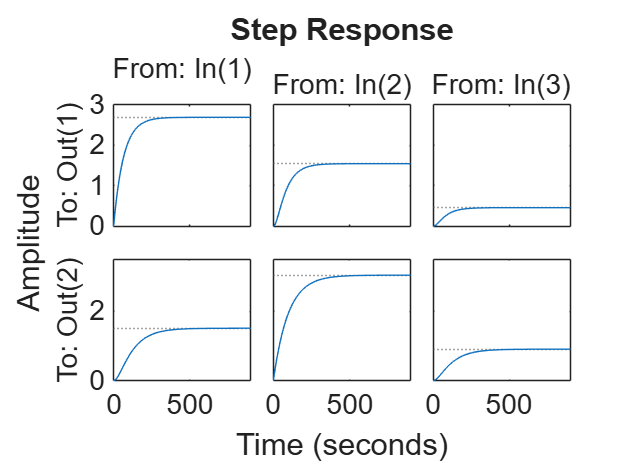

% Generate step response
step( QTank.cmod )

**Task 6:** Now change the operating point corresponding to the **NonMinimum Phase Operating Point** and observe that the model changes and the step responses also change. 

**Task 7:** You can also change the Disturbance input and observe the model step responses. With additional flow the steady state gains increase and the outputs for a unit step change are more as compared to zero disturbance input. 

As can be seen the model consists of constant matrices, which are much easier to analyze, to work with as compared to nonlinear differential equations.  These models will be further used for online simulation. 

## Development of Laplace Transfer Function Matrix Model 

In the first course on control system, a student is introduced to Laplace transfer function models. One we have developed a linear continuous time state space model, it is easy to derive a Laplace transfer function matrix model for the system under consideration. Consider the linear perturbation model given by equation (11) and (12) together with initial condition $x\left(0\right)=\bar{0}$. Taking Laplace transform, we can write 

 $s\;x\left(s\right)-x\left(0\right)=A\;x\left(s\right)+B_u \;u\left(s\right)+B_d \;d\left(s\right)$  ------(15)

and 

$y\left(s\right)=Cx\left(s\right)=C{\left\lbrack s\;I-A\right\rbrack }^{-1} \left\lbrace B_u \;u\left(s\right)+B_d \;d\left(s\right)\right\rbrace$  ------(16)

Defining transfer function matrices 

$G_u \left(s\right)=C{\left\lbrack s\;I-A\right\rbrack }^{-1} B_u \;\;\;\mathrm{and}\;\;G_d \left(s\right)=C{\left\lbrack s\;I-A\right\rbrack }^{-1} B_d \;$   ------(17)

we can arrive at the transfer function model description of the system as follows 

$y\left(s\right)=G_u \left(s\right)\;u\left(s\right)\;+\;\;G_d \left(s\right)d\left(s\right)$  ------(18)

The resulting model can be used for developing controller design methods based on frequency response. Let us develop transfer function model from the state space model. It can be done using MATLAB command [tf](https://in.mathworks.com/help/control/ref/tf.html).

% Develop transfer function model from the state space model 
tf_mod = tf( QTank.cmod )


tf_mod =
 
  From input 1 to output...
         0.04163
   1:  -----------
       s + 0.01547
 
                0.0004322
   2:  ---------------------------
       s^2 + 0.03804 s + 0.0002865
 
  From input 2 to output...
                0.0009561
   1:  ---------------------------
       s^2 + 0.05543 s + 0.0006183
 
         0.03141
   2:  -----------
       s + 0.01035
 
  From input 3 to output...
                0.0002854
   1:  ---------------------------
       s^2 + 0.05543 s + 0.0006183
 
                0.0002596
   2:  ---------------------------
       s^2 + 0.03804 s + 0.0002865
 
Continuous-time transfer function.


Generate frequency response

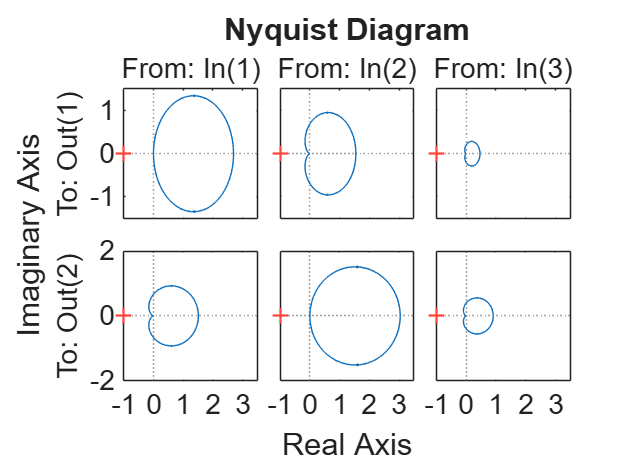

 % Generate frequency response 
 nyquist( tf_mod )

## Conclusion

In this lesson, we saw that a nonlinear ODE model can be converted into a locally linear model expressed in terms of perturbation variables. This form of model is much more convenient as the resulting model is amenable to analytical treatment, when compared with nonlinear ODE models, which need to be solved numerically.   Such a model is a **continuous domain state space model, **which is useful for verifying many important conditions before designing a controller.

## References:

[1] Astrom, K. J., and B. Wittenmark, Computer Controlled Systems, Prentice Hall India (1994).

[2] Franklin, G. F., Powell, J. D., and M. L. Workman, Digital Control Systems, Addison Wesley, 1990. 

[3] Johansson, K. H. (2000). The Quadruple-Tank Process: A multivariable laboratory process with an adjustable zero, IEEE Trans. on Control Systems Technology, 8(3), 456-465.

[4] Marlin, T. E., Process Control, McGraw Hill, 2014. 

[5] Goodwin, G. C., Graebe, S. F.  and M. E. Salgado, Control Systems Design, Prentice Hall India, 2003. 